# The goal for this version is to modify presynaptic cell, to fix the numbers

LGN is still fake, but will add more realistic factors...

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo052921/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Figures/Demo042221/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

load('NtWk_Archit.mat')
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I sparse metrices containing 0 or 1.
% Row_i Column_j means neuron j projects to neuron i add periodic boundary

C_EE_Fix = ConnectionMat_Fix(N_E,NnE,Size_E,...currentVec(2)^2
    N_E,NnE,Size_E,...
    Peak_EE,SD_E,Dist_LB,1, round(N_EE));

Elapsed time is 14.498277 seconds.



C_EI_Fix = ConnectionMat_Fix(N_E,NnE,Size_E,...
    N_I,NnI,Size_I,...
    Peak_I,SD_I,Dist_LB,0, round(N_EI));

Elapsed time is 7.211273 seconds.



C_IE_Fix = ConnectionMat_Fix(N_I,NnI,Size_I,...
    N_E,NnE,Size_E,...
    Peak_I,SD_E,Dist_LB,0, round(N_IE));

Elapsed time is 8.136727 seconds.



C_II_Fix = ConnectionMat_Fix(N_I,NnI,Size_I,...
    N_I,NnI,Size_I,...
    Peak_I,SD_I,Dist_LB,1, round(N_II));

Elapsed time is 2.332500 seconds.


CMatAll = struct('C_EE_Fix',C_EE_Fix,'C_EI_Fix',C_EI_Fix,...
                 'C_IE_Fix',C_IE_Fix,'C_II_Fix',C_II_Fix);

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.5
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Network Simulation

Elapsed time is 5.635621 seconds.
Elapsed time is 8.310682 seconds.
Elapsed time is 11.010403 seconds.
Elapsed time is 13.651142 seconds.
Elapsed time is 16.384323 seconds.
Elapsed time is 19.115911 seconds.
Elapsed time is 21.725828 seconds.
Elapsed time is 24.553735 seconds.


S_EE = 0.024, S_EI = 0.0384, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

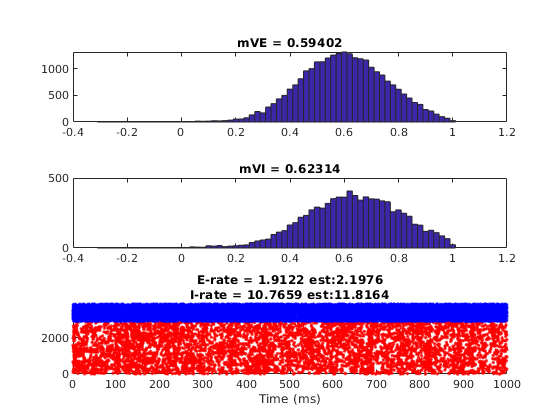

Elapsed time is 28.717629 seconds.
Elapsed time is 31.591144 seconds.
Elapsed time is 34.491885 seconds.
Elapsed time is 37.388463 seconds.
Elapsed time is 40.202388 seconds.


%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.5; N_EEDly = floor(T_EEDly/dt);
T_IEDly = 0.5; N_IEDly = floor(T_IEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% 
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
% N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
InSs = load('Initials_L6.mat');
RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = sparse(N_I,N_IEDly);
%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd,oIEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEnIEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,IEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE_Fix,C_EI_Fix,C_IE_Fix,C_II_Fix,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        %close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end

toc

NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop



## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X),'single');
OD_EMap = zeros(n_E_HC*N_HC,'single');
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
StimulusFac = 1;
lgnE_Drive = [60,50,42,50]*4/1e3 * StimulusFac;
lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(OD_E)';
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
T = 10000; dt = 0.1;
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

%   [A,~,Times] = find(eventsN);
%   R = sparse(A,floor(Times/dt)+1,ones(size(A)),N,length(t));

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = .5; N_EIDly = floor(T_EIDly/dt);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
                                                                GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
if N_EEDly>=size(EndState{19},2)
EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
else
    EEDlyRcd = EndState{19}(:,1:N_EEDly);
end
if N_IEDly>=size(EndState{20},2)
IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
else
    IEDlyRcd = EndState{20}(:,1:N_IEDly);
end
EIDlyRcd = ones(N_E,N_EIDly);
% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

TPar = 10;
for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) + lambda_E_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                      + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                      + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix,C_EI_Fix,C_IE_Fix,C_II_Fix,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
    
     
    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.02;
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs= I_Sp;
              
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrENow = size(E_Sp,1)/N_E/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = ['DriveWkSp_FixPreSynN_LowIto_T' num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','CMatAll','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
end

SampleInd = 2

FrENow = 21.8412

FrINow = 78.1917

Elapsed time is 2.746425 seconds.


SampleInd = 3

FrENow = 14.9337

FrINow = 65.5498

Elapsed time is 4.531938 seconds.


SampleInd = 4

FrENow = 16.5813

FrINow = 69.8324

Elapsed time is 6.931648 seconds.


SampleInd = 5

FrENow = 17.6452

FrINow = 72.9055

Elapsed time is 8.799840 seconds.


SampleInd = 6

FrENow = 15.4740

FrINow = 67.8992

Elapsed time is 11.123602 seconds.


SampleInd = 7

FrENow = 16.6095

FrINow = 70.4683

Elapsed time is 12.982629 seconds.


SampleInd = 8

FrENow = 17.0043

FrINow = 71.5320

Elapsed time is 15.340951 seconds.


SampleInd = 9

FrENow = 15.5906

FrINow = 67.9292

Elapsed time is 17.109729 seconds.


SampleInd = 10

FrENow = 17.4166

FrINow = 72.4847

Elapsed time is 19.439989 seconds.


SampleInd = 11

FrENow = 15.7202

FrINow = 68.4680

Elapsed time is 21.234288 seconds.


SampleInd = 12

FrENow = 16.1195

FrINow = 69.3699

Elapsed time is 23.530987 seconds.


SampleInd = 13

FrENow = 15.6523

FrINow = 68.2137

Elapsed time is 25.227506 seconds.


SampleInd = 14

FrENow = 17.2657

FrINow = 72.0222

Elapsed time is 27.570776 seconds.


SampleInd = 15

FrENow = 16.4914

FrINow = 70.2255

Elapsed time is 29.278333 seconds.


SampleInd = 16

FrENow = 16.6811

FrINow = 70.7041

Elapsed time is 31.621104 seconds.


SampleInd = 17

FrENow = 16.4548

FrINow = 70.3249

Elapsed time is 33.449369 seconds.


SampleInd = 18

FrENow = 16.6293

FrINow = 70.4567

Elapsed time is 35.843066 seconds.


SampleInd = 19

FrENow = 16.9753

FrINow = 71.2984

Elapsed time is 37.719792 seconds.


SampleInd = 20

FrENow = 15.8223

FrINow = 68.9583

Elapsed time is 40.008842 seconds.


SampleInd = 21

FrENow = 16.7886

FrINow = 71.0695

Elapsed time is 41.790136 seconds.


Elapsed time is 41.790974 seconds.


SampleInd = 22

FrENow = 16.6027

FrINow = 70.2740

Elapsed time is 2.412968 seconds.


SampleInd = 23

FrENow = 16.1683

FrINow = 69.3398

Elapsed time is 4.313550 seconds.


SampleInd = 24

FrENow = 17.1948

FrINow = 72.3760

Elapsed time is 6.763965 seconds.


SampleInd = 25

FrENow = 15.9381

FrINow = 68.9236

Elapsed time is 8.609754 seconds.


SampleInd = 26

FrENow = 16.4457

FrINow = 70.1191

Elapsed time is 11.031376 seconds.


SampleInd = 27

FrENow = 16.6811

FrINow = 70.6903

Elapsed time is 12.901999 seconds.


SampleInd = 28

FrENow = 17.4364

FrINow = 72.7645

Elapsed time is 15.405532 seconds.


SampleInd = 29

FrENow = 16.3039

FrINow = 70.1098

Elapsed time is 17.213246 seconds.


SampleInd = 30

FrENow = 15.9191

FrINow = 68.8866

Elapsed time is 19.538742 seconds.


SampleInd = 31

FrENow = 16.4967

FrINow = 70.1330

Elapsed time is 21.329713 seconds.


SampleInd = 32

FrENow = 16.3603

FrINow = 70.0867

Elapsed time is 23.633497 seconds.


SampleInd = 33

FrENow = 15.6653

FrINow = 68.2229

Elapsed time is 25.318129 seconds.


SampleInd = 34

FrENow = 17.0904

FrINow = 71.3886

Elapsed time is 27.720555 seconds.


SampleInd = 35

FrENow = 16.0913

FrINow = 69.4577

Elapsed time is 29.509482 seconds.


SampleInd = 36

FrENow = 16.3588

FrINow = 69.9457

Elapsed time is 31.903264 seconds.


SampleInd = 37

FrENow = 16.7200

FrINow = 71.1111

Elapsed time is 33.780942 seconds.


SampleInd = 38

FrENow = 15.7926

FrINow = 68.6923

Elapsed time is 36.069250 seconds.


SampleInd = 39

FrENow = 17.8433

FrINow = 73.6779

Elapsed time is 37.954411 seconds.


SampleInd = 40

FrENow = 15.2096

FrINow = 67.2124

Elapsed time is 40.201476 seconds.


SampleInd = 41

FrENow = 16.7497

FrINow = 71.0256

Elapsed time is 42.027937 seconds.


Elapsed time is 42.028720 seconds.


SampleInd = 42

FrENow = 16.9982

FrINow = 71.3609

Elapsed time is 2.398471 seconds.


SampleInd = 43

FrENow = 16.3062

FrINow = 69.8231

Elapsed time is 4.207743 seconds.


SampleInd = 44

FrENow = 16.8412

FrINow = 71.4441

Elapsed time is 6.582801 seconds.


SampleInd = 45

FrENow = 16.3794

FrINow = 70.0335

Elapsed time is 8.434280 seconds.


SampleInd = 46

FrENow = 17.0980

FrINow = 72.0430

Elapsed time is 10.851820 seconds.


SampleInd = 47

FrENow = 16.8983

FrINow = 71.4950

Elapsed time is 12.686570 seconds.


SampleInd = 48

FrENow = 15.5175

FrINow = 68.2021

Elapsed time is 15.020286 seconds.


SampleInd = 49

FrENow = 16.9319

FrINow = 71.2059

Elapsed time is 16.903844 seconds.


SampleInd = 50

FrENow = 16.8762

FrINow = 71.2984

Elapsed time is 19.326559 seconds.


SampleInd = 51

FrENow = 15.6722

FrINow = 68.1882

Elapsed time is 21.130229 seconds.


SampleInd = 52

FrENow = 16.7596

FrINow = 70.9007

Elapsed time is 23.528949 seconds.


SampleInd = 53

FrENow = 16.0273

FrINow = 69.0068

Elapsed time is 25.296786 seconds.


SampleInd = 54

FrENow = 16.6781

FrINow = 70.9539

Elapsed time is 27.644995 seconds.


SampleInd = 55

FrENow = 17.1788

FrINow = 72.0939

Elapsed time is 29.514830 seconds.


SampleInd = 56

FrENow = 16.8846

FrINow = 71.3817

Elapsed time is 31.824838 seconds.


SampleInd = 57

FrENow = 16.6606

FrINow = 70.8197

Elapsed time is 33.558110 seconds.


SampleInd = 58

FrENow = 14.7935

FrINow = 66.2689

Elapsed time is 35.801919 seconds.


SampleInd = 59

FrENow = 17.9188

FrINow = 73.5368

Elapsed time is 37.752527 seconds.


SampleInd = 60

FrENow = 16.1302

FrINow = 69.6844

Elapsed time is 40.000805 seconds.


SampleInd = 61

FrENow = 17.3053

FrINow = 72.3043

Elapsed time is 41.880504 seconds.


Elapsed time is 41.881287 seconds.


SampleInd = 62

FrENow = 15.5289

FrINow = 68.1790

Elapsed time is 2.245830 seconds.


SampleInd = 63

FrENow = 16.6011

FrINow = 70.4937

Elapsed time is 4.117890 seconds.


SampleInd = 64

FrENow = 16.3214

FrINow = 69.8162

Elapsed time is 6.467143 seconds.


SampleInd = 65

FrENow = 16.6651

FrINow = 71.0903

Elapsed time is 8.334704 seconds.


SampleInd = 66

FrENow = 15.1471

FrINow = 66.7869

Elapsed time is 10.659343 seconds.


SampleInd = 67

FrENow = 16.6537

FrINow = 70.3503

Elapsed time is 12.508105 seconds.


SampleInd = 68

FrENow = 17.4851

FrINow = 72.5541

Elapsed time is 14.851867 seconds.


SampleInd = 69

FrENow = 16.4464

FrINow = 70.3249

Elapsed time is 16.695044 seconds.


SampleInd = 70

FrENow = 16.7452

FrINow = 70.9770

Elapsed time is 19.050155 seconds.


SampleInd = 71

FrENow = 17.1239

FrINow = 71.8303

Elapsed time is 20.790558 seconds.


SampleInd = 72

FrENow = 16.1408

FrINow = 69.7075

Elapsed time is 23.101082 seconds.


SampleInd = 73

FrENow = 15.3338

FrINow = 67.4113

Elapsed time is 24.832299 seconds.


SampleInd = 74

FrENow = 17.0660

FrINow = 71.6152

Elapsed time is 27.224334 seconds.


SampleInd = 75

FrENow = 16.7650

FrINow = 71.0533

Elapsed time is 28.986557 seconds.


SampleInd = 76

FrENow = 16.6804

FrINow = 70.9701

Elapsed time is 31.323114 seconds.


SampleInd = 77

FrENow = 15.8695

FrINow = 68.6137

Elapsed time is 33.030219 seconds.


SampleInd = 78

FrENow = 17.0759

FrINow = 71.7748

Elapsed time is 35.397131 seconds.


SampleInd = 79

FrENow = 16.7802

FrINow = 71.2545

Elapsed time is 37.236863 seconds.


SampleInd = 80

FrENow = 15.9183

FrINow = 68.9675

Elapsed time is 39.563729 seconds.


SampleInd = 81

FrENow = 16.1904

FrINow = 69.6959

Elapsed time is 41.294525 seconds.


Elapsed time is 41.295254 seconds.


SampleInd = 82

FrENow = 16.5409

FrINow = 70.2925

Elapsed time is 2.349137 seconds.


SampleInd = 83

FrENow = 16.0844

FrINow = 69.4138

Elapsed time is 4.096399 seconds.


SampleInd = 84

FrENow = 16.9570

FrINow = 71.3262

Elapsed time is 6.518811 seconds.


SampleInd = 85

FrENow = 16.1927

FrINow = 69.5988

Elapsed time is 8.333012 seconds.


SampleInd = 86

FrENow = 17.1963

FrINow = 71.9528

Elapsed time is 10.714434 seconds.


SampleInd = 87

FrENow = 16.8130

FrINow = 71.2013

Elapsed time is 12.596719 seconds.


SampleInd = 88

FrENow = 16.3740

FrINow = 70.2879

Elapsed time is 14.985157 seconds.


SampleInd = 89

FrENow = 16.9319

FrINow = 71.2452

Elapsed time is 16.866475 seconds.


SampleInd = 90

FrENow = 15.5243

FrINow = 68.1512

Elapsed time is 19.143172 seconds.


SampleInd = 91

FrENow = 17.1750

FrINow = 71.6615

Elapsed time is 20.976060 seconds.


SampleInd = 92

FrENow = 16.0860

FrINow = 69.1756

Elapsed time is 23.216043 seconds.


SampleInd = 93

FrENow = 16.6286

FrINow = 70.7088

Elapsed time is 24.981867 seconds.


SampleInd = 94

FrENow = 15.5495

FrINow = 67.9709

Elapsed time is 27.275432 seconds.


SampleInd = 95

FrENow = 16.6202

FrINow = 70.3711

Elapsed time is 29.089425 seconds.


SampleInd = 96

FrENow = 16.5973

FrINow = 70.2440

Elapsed time is 31.479023 seconds.


SampleInd = 97

FrENow = 16.4464

FrINow = 70.3434

Elapsed time is 33.270583 seconds.


SampleInd = 98

FrENow = 16.2993

FrINow = 69.7375

Elapsed time is 35.617809 seconds.


SampleInd = 99

FrENow = 16.2833

FrINow = 69.6497

Elapsed time is 37.333585 seconds.


SampleInd = 100

FrENow = 16.3641

FrINow = 70.0520

Elapsed time is 39.644516 seconds.


SampleInd = 101

FrENow = 15.4763

FrINow = 67.4991

Elapsed time is 41.280186 seconds.


Elapsed time is 41.281018 seconds.


SampleInd = 102

FrENow = 17.8555

FrINow = 73.4351

Elapsed time is 2.409271 seconds.


SampleInd = 103

FrENow = 15.3567

FrINow = 67.7049

Elapsed time is 4.233538 seconds.


SampleInd = 104

FrENow = 15.9419

FrINow = 68.9583

Elapsed time is 6.502488 seconds.


SampleInd = 105

FrENow = 17.0203

FrINow = 71.4927

Elapsed time is 8.312450 seconds.


SampleInd = 106

FrENow = 17.7503

FrINow = 73.7611

Elapsed time is 10.762122 seconds.


SampleInd = 107

FrENow = 15.9427

FrINow = 69.3768

Elapsed time is 12.588694 seconds.


SampleInd = 108

FrENow = 16.3420

FrINow = 70.1145

Elapsed time is 14.936328 seconds.


SampleInd = 109

FrENow = 16.6240

FrINow = 70.8313

Elapsed time is 16.721900 seconds.


SampleInd = 110

FrENow = 15.9930

FrINow = 68.6438

Elapsed time is 19.090112 seconds.


SampleInd = 111

FrENow = 16.5242

FrINow = 70.3365

Elapsed time is 20.841161 seconds.


SampleInd = 112

FrENow = 16.8107

FrINow = 71.3886

Elapsed time is 23.274161 seconds.


SampleInd = 113

FrENow = 16.1904

FrINow = 69.5618

Elapsed time is 25.096805 seconds.


SampleInd = 114

FrENow = 16.3298

FrINow = 69.9063

Elapsed time is 27.365664 seconds.


SampleInd = 115

FrENow = 16.5203

FrINow = 70.2509

Elapsed time is 29.174137 seconds.


SampleInd = 116

FrENow = 16.0661

FrINow = 69.1779

Elapsed time is 31.481500 seconds.


SampleInd = 117

FrENow = 15.5594

FrINow = 67.9107

Elapsed time is 33.167145 seconds.


SampleInd = 118

FrENow = 17.6513

FrINow = 73.0790

Elapsed time is 35.616811 seconds.


SampleInd = 119

FrENow = 16.2574

FrINow = 69.4485

Elapsed time is 37.356673 seconds.


SampleInd = 120

FrENow = 17.8022

FrINow = 73.3264

Elapsed time is 39.695227 seconds.


SampleInd = 121

FrENow = 15.2972

FrINow = 67.5870

Elapsed time is 41.390482 seconds.


Elapsed time is 41.391194 seconds.


SampleInd = 122

FrENow = 17.0637

FrINow = 71.4649

Elapsed time is 2.466303 seconds.


SampleInd = 123

FrENow = 16.9585

FrINow = 71.6383

Elapsed time is 4.339899 seconds.


SampleInd = 124

FrENow = 16.2170

FrINow = 69.7005

Elapsed time is 6.704143 seconds.


SampleInd = 125

FrENow = 16.6004

FrINow = 70.6533

Elapsed time is 8.533942 seconds.


SampleInd = 126

FrENow = 16.3550

FrINow = 70.2532

Elapsed time is 10.952206 seconds.


SampleInd = 127

FrENow = 17.2436

FrINow = 72.2835

Elapsed time is 12.854507 seconds.


SampleInd = 128

FrENow = 16.8092

FrINow = 71.2290

Elapsed time is 15.224832 seconds.


SampleInd = 129

FrENow = 16.1949

FrINow = 69.8994

Elapsed time is 17.024651 seconds.


SampleInd = 130

FrENow = 16.2346

FrINow = 69.8578

Elapsed time is 19.371901 seconds.


SampleInd = 131

FrENow = 16.1576

FrINow = 69.4392

Elapsed time is 21.157034 seconds.


SampleInd = 132

FrENow = 16.6949

FrINow = 70.7827

Elapsed time is 23.509201 seconds.


SampleInd = 133

FrENow = 16.6659

FrINow = 70.8082

Elapsed time is 25.342392 seconds.


SampleInd = 134

FrENow = 17.0622

FrINow = 71.9320

Elapsed time is 27.698624 seconds.


SampleInd = 135

FrENow = 15.3010

FrINow = 67.2656

Elapsed time is 29.427690 seconds.


SampleInd = 136

FrENow = 16.5371

FrINow = 70.3457

Elapsed time is 31.796746 seconds.


SampleInd = 137

FrENow = 16.5905

FrINow = 70.3203

Elapsed time is 33.528715 seconds.


SampleInd = 138

FrENow = 16.1020

FrINow = 69.3514

Elapsed time is 35.841854 seconds.


SampleInd = 139

FrENow = 16.8892

FrINow = 71.4210

Elapsed time is 37.685901 seconds.


SampleInd = 140

FrENow = 16.2696

FrINow = 70.1191

Elapsed time is 40.001666 seconds.


SampleInd = 141

FrENow = 16.5386

FrINow = 70.2948

Elapsed time is 41.706312 seconds.


Elapsed time is 41.707010 seconds.


SampleInd = 142

FrENow = 16.6095

FrINow = 70.6440

Elapsed time is 2.336382 seconds.


SampleInd = 143

FrENow = 16.9745

FrINow = 71.7470

Elapsed time is 4.154278 seconds.


SampleInd = 144

FrENow = 16.1812

FrINow = 69.4693

Elapsed time is 6.523205 seconds.


SampleInd = 145

FrENow = 16.5272

FrINow = 70.5561

Elapsed time is 8.359774 seconds.


SampleInd = 146

FrENow = 16.0372

FrINow = 69.2288

Elapsed time is 10.662184 seconds.


SampleInd = 147

FrENow = 17.0302

FrINow = 71.7193

Elapsed time is 12.573483 seconds.


SampleInd = 148

FrENow = 15.7225

FrINow = 68.2877

Elapsed time is 14.828472 seconds.


SampleInd = 149

FrENow = 17.7953

FrINow = 73.6016

Elapsed time is 16.665445 seconds.


SampleInd = 150

FrENow = 16.3382

FrINow = 70.2601

Elapsed time is 19.084028 seconds.


SampleInd = 151

FrENow = 17.3007

FrINow = 72.3251

Elapsed time is 20.979712 seconds.


SampleInd = 152

FrENow = 15.4268

FrINow = 67.9200

Elapsed time is 23.293854 seconds.


SampleInd = 153

FrENow = 17.0957

FrINow = 71.8071

Elapsed time is 25.215905 seconds.


SampleInd = 154

FrENow = 16.0059

FrINow = 69.3583

Elapsed time is 27.588436 seconds.


SampleInd = 155

FrENow = 16.8480

FrINow = 71.2244

Elapsed time is 29.460543 seconds.


SampleInd = 156

FrENow = 16.9227

FrINow = 71.3262

Elapsed time is 31.826937 seconds.


SampleInd = 157

FrENow = 16.5981

FrINow = 70.4359

Elapsed time is 33.659002 seconds.


SampleInd = 158

FrENow = 16.0905

FrINow = 69.4323

Elapsed time is 36.026886 seconds.


SampleInd = 159

FrENow = 17.2390

FrINow = 72.5263

Elapsed time is 37.837822 seconds.


SampleInd = 160

FrENow = 16.9509

FrINow = 71.7447

Elapsed time is 40.165755 seconds.


SampleInd = 161

FrENow = 15.0907

FrINow = 66.9025

Elapsed time is 41.783837 seconds.


Elapsed time is 41.784541 seconds.


SampleInd = 162

FrENow = 17.4676

FrINow = 72.4847

Elapsed time is 2.444329 seconds.


SampleInd = 163

FrENow = 16.6964

FrINow = 70.7758

Elapsed time is 4.286605 seconds.


SampleInd = 164

FrENow = 16.3283

FrINow = 69.9063

Elapsed time is 6.696408 seconds.


SampleInd = 165

FrENow = 16.1568

FrINow = 69.6520

Elapsed time is 8.538228 seconds.


SampleInd = 166

FrENow = 15.8932

FrINow = 68.9259

Elapsed time is 10.837455 seconds.


SampleInd = 167

FrENow = 16.6469

FrINow = 70.4243

Elapsed time is 12.675152 seconds.


SampleInd = 168

FrENow = 17.2314

FrINow = 72.2396

Elapsed time is 15.009606 seconds.


SampleInd = 169

FrENow = 15.7827

FrINow = 68.5860

Elapsed time is 16.806889 seconds.


SampleInd = 170

FrENow = 16.6484

FrINow = 70.6024

Elapsed time is 19.157083 seconds.


SampleInd = 171

FrENow = 15.4130

FrINow = 67.4459

Elapsed time is 20.805783 seconds.


SampleInd = 172

FrENow = 17.0050

FrINow = 71.3840

Elapsed time is 23.100155 seconds.


SampleInd = 173

FrENow = 17.1574

FrINow = 72.0060

Elapsed time is 24.868002 seconds.


SampleInd = 174

FrENow = 16.0151

FrINow = 69.2450

Elapsed time is 27.143253 seconds.


SampleInd = 175

FrENow = 17.1171

FrINow = 72.1193

Elapsed time is 29.035950 seconds.


SampleInd = 176

FrENow = 16.5066

FrINow = 70.3018

Elapsed time is 31.348092 seconds.


SampleInd = 177

FrENow = 16.9136

FrINow = 71.4580

Elapsed time is 33.200215 seconds.


SampleInd = 178

FrENow = 15.7567

FrINow = 68.4912

Elapsed time is 35.460242 seconds.


SampleInd = 179

FrENow = 16.5935

FrINow = 70.5954

Elapsed time is 37.276685 seconds.


SampleInd = 180

FrENow = 16.4266

FrINow = 69.8832

Elapsed time is 39.650961 seconds.


SampleInd = 181

FrENow = 16.9944

FrINow = 71.5805

Elapsed time is 41.479800 seconds.


Elapsed time is 41.480572 seconds.


SampleInd = 182

FrENow = 15.9275

FrINow = 68.9236

Elapsed time is 2.370673 seconds.


SampleInd = 183

FrENow = 16.8648

FrINow = 71.1273

Elapsed time is 4.232049 seconds.


SampleInd = 184

FrENow = 16.6735

FrINow = 70.9631

Elapsed time is 6.649424 seconds.


SampleInd = 185

FrENow = 15.6561

FrINow = 68.2923

Elapsed time is 8.470489 seconds.


SampleInd = 186

FrENow = 16.7551

FrINow = 70.9377

Elapsed time is 10.877361 seconds.


SampleInd = 187

FrENow = 16.7977

FrINow = 71.0186

Elapsed time is 12.746391 seconds.


SampleInd = 188

FrENow = 15.4298

FrINow = 68.0564

Elapsed time is 14.965464 seconds.


SampleInd = 189

FrENow = 17.3350

FrINow = 71.9945

Elapsed time is 16.861180 seconds.


SampleInd = 190

FrENow = 16.2003

FrINow = 69.6080

Elapsed time is 19.167842 seconds.


SampleInd = 191

FrENow = 16.0806

FrINow = 69.2173

Elapsed time is 20.988166 seconds.


SampleInd = 192

FrENow = 17.1773

FrINow = 72.1332

Elapsed time is 23.421629 seconds.


SampleInd = 193

FrENow = 16.9936

FrINow = 71.4927

Elapsed time is 25.242623 seconds.


SampleInd = 194

FrENow = 15.5639

FrINow = 68.3547

Elapsed time is 27.556006 seconds.


SampleInd = 195

FrENow = 17.3106

FrINow = 72.1725

Elapsed time is 29.463222 seconds.


SampleInd = 196

FrENow = 15.4534

FrINow = 67.9339

Elapsed time is 31.775530 seconds.


SampleInd = 197

FrENow = 16.8458

FrINow = 71.1574

Elapsed time is 33.538475 seconds.


SampleInd = 198

FrENow = 16.8480

FrINow = 71.2730

Elapsed time is 35.915352 seconds.


SampleInd = 199

FrENow = 16.6766

FrINow = 70.7157

Elapsed time is 37.757784 seconds.


SampleInd = 200

FrENow = 15.9747

FrINow = 69.1849

Elapsed time is 39.993688 seconds.


SampleInd = 201

FrENow = 17.4501

FrINow = 72.6026

Elapsed time is 41.787891 seconds.


Elapsed time is 41.788868 seconds.


Plot Spatial maps: load data

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 1:TPar
    text = ['DriveWkSp_FixPreSynN_LowIto_T' num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
WinSize = StatWin(2) - StatWin(1);

% Check soome time dependency// cental hypercolum??
Opt = OD_E==1;
Worst = OD_E==3;
Nor = OD_E==2 | OD_E==4;

MidColE = NnE.X>=n_E_HC & NnE.X<=2*n_E_HC;
MidRowE = NnE.Y>=n_E_HC & NnE.Y<=2*n_E_HC;
MidHCE = MidColE & MidRowE;

ShowWin = [8000 9000]

ShowWin =         8000        9000


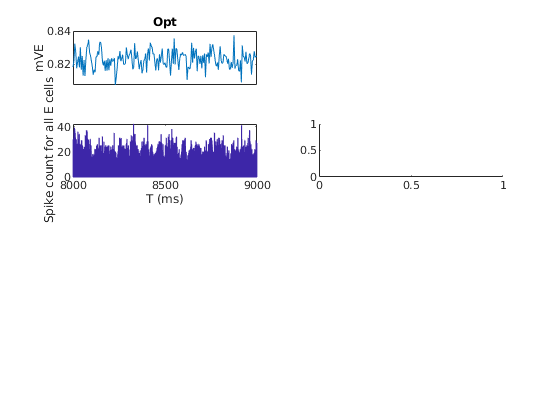

figure('Name','Theta')
subplot 423
hist(SpE(ismember(SpE(:,1),find(Opt & MidHCE)),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 421
plot(StatWin(1:WinNum),nanmean(mVI(OD_I'==1,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

subplot 424

hist(SpE(ismember(SpE(:,1),find(Worst & MidHCE)),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 422
plot(StatWin(1:WinNum),nanmean(mVI(OD_I'==3,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

subplot 427
hist(SpE(ismember(SpE(:,1),find(Nor & MidHCE)),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 425
plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
ylabel('mVE')
set(gca,'xtick','')
xlim(ShowWin)

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);
% hist(SpE(ismember(SpE(:,1),OptOne),2),0:1:T)

Plot Spatial maps: Plot

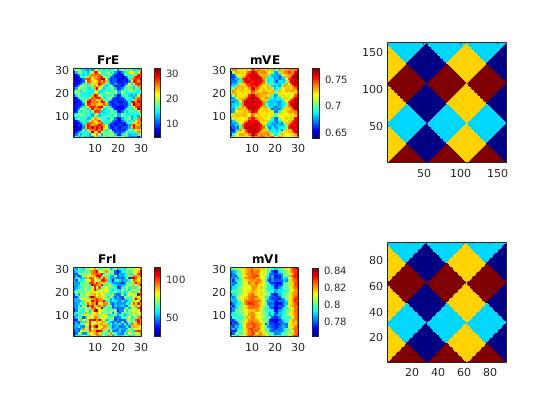

WinSize = 7500;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));

h = figure('Name','Field_f&V');

% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

subplot 231
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

[FrEPixMat,NnEPixel] = NeuVec2Pixel(FrE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 232
mVE_temp = nanmean(mVE(:,SmallWinRange),2);
mVE_Map = reshape(mVE_temp,N_HC*n_E_HC,N_HC*n_E_HC);

[mVEPixMat,~] = NeuVec2Pixel(mVE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEPixMat); title('mVE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')


% end of 500ms plot

    


%save('DriveWkSp.mat')

## MF linear equation for pixels: 1 Matrices

FrEPixVec = reshape(FrEPixMat,NPixX*N_HC*NPixY*N_HC,1);
FrIPixVec = reshape(FrIPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVEPixVec = reshape(mVEPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVIPixVec = reshape(mVIPixMat,NPixX*N_HC*NPixY*N_HC,1);
% First, get connectivity matrix between Pixels
C_EE_Pixel = zeros(length(FrEPixVec));
C_EI_Pixel = zeros(length(FrEPixVec));
C_IE_Pixel = zeros(length(FrEPixVec));
C_II_Pixel = zeros(length(FrEPixVec));
% look into std as well
C_EE_Pixelstd = zeros(length(FrEPixVec));
C_EI_Pixelstd = zeros(length(FrEPixVec));
C_IE_Pixelstd = zeros(length(FrEPixVec));
C_II_Pixelstd = zeros(length(FrEPixVec));
tic
AA = length(FrEPixVec);
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_EE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EE_Fix(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EI_Fix(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_IE_Fix(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixel(PixIndPost,PixIndPre) = mean(sum(C_II_Fix(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE_Fix(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI_Fix(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE_Fix(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II_Fix(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end
toc

Elapsed time is 51.254423 seconds.


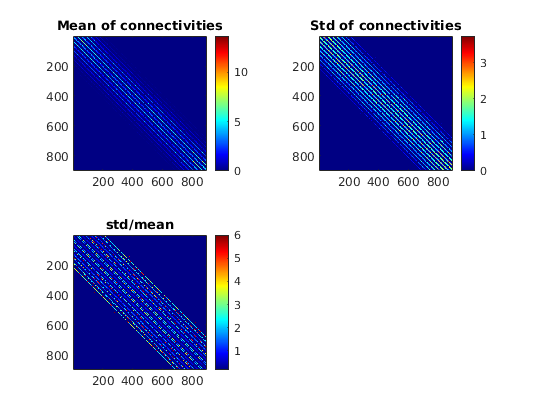

C_EE_Pixel_Us = sparse(C_EE_Pixel);
C_IE_Pixel_Us = sparse(C_IE_Pixel);
C_EI_Pixel_Us = sparse(C_EI_Pixel);
C_II_Pixel_Us = sparse(C_II_Pixel);

% Present connectivity mats
figure
subplot 221
imagesc(C_EE_Pixel)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_EE_Pixelstd)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_EE_Pixelstd./C_EE_Pixel)
axis square
colorbar
title('std/mean')

MF linear equation for pixels: 2 MF Eqns

% Mats
MatEE = (S_EE*(1-p_EEFail))*C_EE_Pixel_Us.*(Ve-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC)); % Need Ref here??
MatEI = S_EI *              C_EI_Pixel_Us.*(Vi-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatIE = S_IE *              C_IE_Pixel_Us.*(Ve-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatII = S_II *              C_II_Pixel_Us.*(Vi-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
ConnMat = [MatEE,MatEI;MatIE,MatII];
% Leak
LeakE = gL_E * (0-mVEPixVec) * 1e3;
LeakI = gL_I * (0-mVIPixVec) * 1e3;
LeakV = [LeakE;LeakI];
% Ext
lambda_E_Pixel = zeros(size(mVEPixVec));
L6E_Pixel = zeros(size(mVEPixVec));
L6I_Pixel = zeros(size(mVEPixVec));
for PixInd = 1:length(FrEPixVec)
    lambda_E_Pixel(PixInd) = mean(lambda_E_drive(NnEPixel.Vec == PixInd));
    L6E_Pixel(PixInd) = mean(rE_L6_Drive(NnEPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive;

ExtE = (lambda_E_Pixel*S_Elgn + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEPixVec) * 1e3;
ExtI = (lambda_I_Pixel*S_Ilgn + rI_amb*S_amb + L6I_Pixel*S_IL6).*(Ve-mVIPixVec) * 1e3;
ExtV = [ExtE;ExtI];
% Ref Vec
RefE = 1-FrEPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = sparse(diag([RefE;RefI]));
% L4 Frs
Fr_L4 = [FrEPixVec;FrIPixVec];

% MF Equations:
Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
Fr_MFinv = (sparse(eye(2*NPixX*N_HC*NPixY*N_HC))-RefM*ConnMat)^-1 * (RefM * ( ExtV + LeakV));

% Err
FrErr = Fr_MFinv - Fr_L4;

EPixRange = [0 40];
IPixRange = [10 120];

figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)
caxis(EPixRange);

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)
caxis(IPixRange);

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = reshape(Fr_MFinv(1:length(FrEPixVec)),NPixY*N_HC,NPixX*N_HC)

FrEPixMat_MF =    -2.9103    6.7630    9.6784    9.5307   16.6193   17.9013   18.9770   19.7797   13.8514   19.2043   18.9826    7.6083    6.5304    4.9841    8.3911    3.7423    7.2599   13.9592   14.6046   13.3298   15.1174   23.2567   21.0011   19.6888   14.2956   15.0792   12.8982    0.1048   -3.8650   -9.6715
   -1.8589    4.6924   13.6926   17.0238   12.6926   15.9200   17.0137   16.6229   20.1434   28.2523   24.8125   22.4528   10.7882    6.8299    9.0288    8.9390    8.6607   13.4372   14.4342    4.8256    6.5525   10.2658   18.8637   16.8520   16.1966   15.7238   12.8077    5.4952    4.1532    9.3656
    3.5886    3.9041   12.1888   14.0837   13.2477   16.6539   12.1579   16.6394   23.0021   26.3372   27.7329   22.9639   20.9821   12.8691    7.5544   11.3723   11.2709    7.4664    4.4544    3.3322    8.5923    4.6336    9.5938   17.9941   17.1655   16.3591   11.7697   17.0130   20.1134   19.4063
    9.0381    6.4588    4.9498   12.7162   15.4637   12.3563   15.9460   27.6534  

imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)
caxis(EPixRange);

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(length(FrEPixVec)+1:end),NPixY*N_HC,NPixX*N_HC)

FrIPixMat_MF =    31.5450   54.6444   56.6142   69.3610   37.1202   64.1505   72.6707   61.7745   70.7999   65.7124   89.1727   55.6855   62.6438   68.8489   65.5075   46.8774   34.1728   49.4735   65.5003   43.0971   44.0743   64.8853   70.6648   49.6952   61.7269   67.1644   57.0478   54.8392   38.6449   78.1351
   34.7742   30.8760   54.5956   71.2058   79.9868   67.5128   76.8294   76.9062   81.4209  113.2150   94.2265   99.0589   61.4550   54.6384   59.3053   63.2908   55.2706   59.2882   45.6798   35.9826   15.9553   52.7439   64.7361   70.3719   51.6702   59.7130   75.0880   65.0464   62.1273   85.9986
   33.3364   38.5575   50.3611   70.7439   64.0549   71.5807   70.6431   77.1843   96.0734   97.4190   90.8226   84.4110   76.1776   64.7512   67.8385   56.9455   59.4001   60.8566   33.5429   44.0960   48.4538   44.8710   61.5178   94.6445   62.4742   66.2580   62.1928   89.9990   91.5705   89.9098
   29.4292   55.0637   36.5348   43.4292   81.0958   51.7389   63.8895   95.7188  

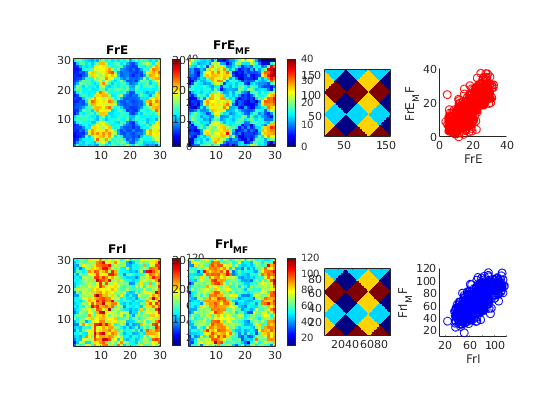

imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)
caxis(IPixRange);

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
scatter(FrEPixVec,Fr_MFinv(1:NPixX*N_HC*NPixY*N_HC),'ro')
axis([EPixRange EPixRange])
axis square
xlabel('FrE'); ylabel('FrE_MF')

subplot 248
scatter(FrIPixVec,Fr_MFinv(NPixX*N_HC*NPixY*N_HC+1:end),'bo')
 axis([IPixRange IPixRange])
axis square
xlabel('FrI'); ylabel('FrI_MF')

Now go MF+v